# Homework 02 - Digital Signal Processing & Error

Please add your name, section, and semester information to the fields below

StudentName = "Edward Ramirez"; % First Last
Section = "A09"; % ex. A01
Semester = "Spring 2025"; % ex. Fall 2023

## Background

For this lab block you will be investigating reducing measurement error of a custom SONAR system. Error reduction will be accomplished by using signal processing to mitigate the effects of noise and accounting for a reference bias in your measurements. The proposed SONAR system (Figure 1) uses a signal generator, power amplifier, and speaker to provide an audio signal and a microphone to measure the signal reflection of objects. The microphone is attached to a boom that extends and swings, with encoders to track its location, which will be used to measure the pressure wave from the speaker and the reflection off a target object. The microphone acts as a transducer that converts the acoustic energy of the pressure wave into a voltage that can be acquired.

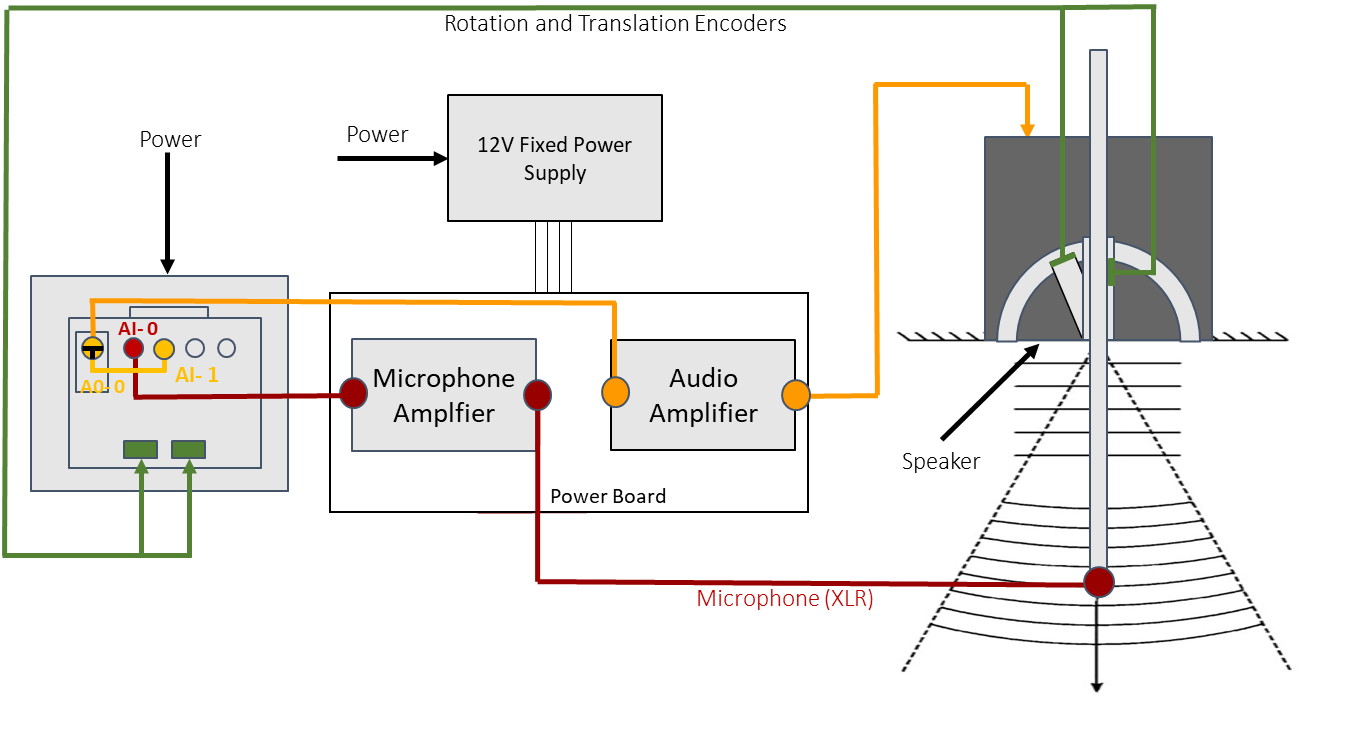

*Figure 1*:* Schematic of custom SONAR system to determining the distance of objects relative to the speaker.*

## Data

This homework will focus on the preliminary signal processing that will be used in your analysis. A sample dataset, *Homework_2_SONAR_Data.mat*, that you will use in this homework analysis can found in the assignment on Canvas.

load( 'Homework_2_SONAR_Data.mat' );

% Datasets
time_s; % s, time vector of signals in seconds
input_V; % V, voltage vector of commanded signal to speaker
target_V; % V, 5 voltage column vectors of microphone data with target object 
baseline_V; % V, 5 voltage column vectors of microphone data without target object 

## Signal Processing

The raw signal collected during the SONAR experiments will include the noise within the operating range of the microphone, making it difficult to identify the reflection of the sound wave off the target object. This can include ambient random noise or systematic baseline noise. In addition to this, the sound pressure level decreases with distance, so the magnitude of the reflected wave may be much smaller than that of the noise. An example of this is shown in Figure 2, where the wave initially passing the microphone is clearly visible, but there are multiple fluctuations in the signal that could come from the sound’s reflection off the target object. Signal processing can be used to increase the signal to noise ratio (SNR) so that key features, such as when the acoustic wave passes by the microphone before and after reflection off the target, can be identified.

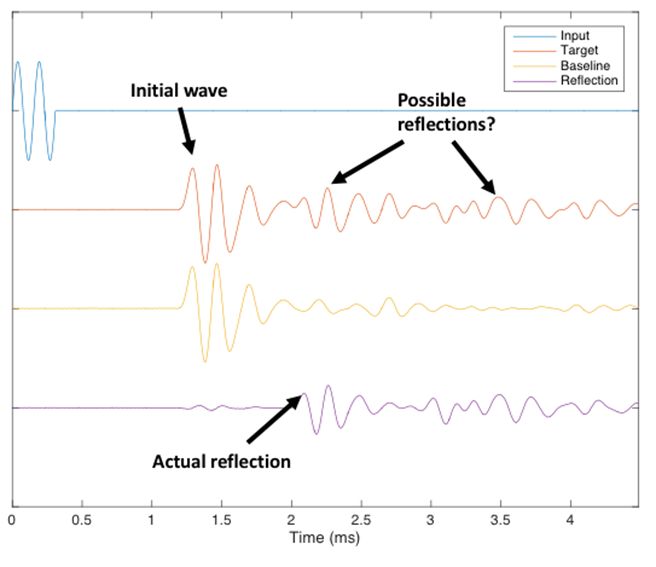

*Figure 2: The raw microphone signal data from SONAR experiment can be difficult to analyze due to signal noise. The initial pass of the acoustic wave by the microphone is easily identifiable; however, there are multiple features in the signal that look like they could represent the reflected wave. Comparative signal processing of the target signal versus a baseline signal can be used to help identify the target reflection.*

### Random Noise

As you saw in the previous lab block, random noise can be removed from signals using filters. However, if the random noise is in the frequency range of the signal of interest, such a random acoustic noise during the SONAR experiment, this is not possible as it may attenuate the signal of interest. A common method in experimentation to improve SNR is to collect and average multiple signals. This will attenuate random noise in the signal. Since the digital signals collected in this lab are discretized in time, you can average data from multiple signals at the same time step to improve SNR. 

#### Problem 1

*Homework_2_SONAR_Data.mat *contains 5 sample signals with the target object saved as *target_V* with each sample as a column in the matrix. Average the 5 target signals to improve the SNR of the target signal by averaging the data at each time step.

*(Note: You should end up with a vector the same size as the time vector *time_s**.***)*

targetAveraged_V = mean(target_V, 2); % V

### Systematic Noise

Systematic sources of noise on the signal cannot be reduced by averaging at it will repeat in the same manner every time a signal is collected. For example, an object that is not moving relative to the system could cause a reflection which may mask the reflection of the target object. These sources of noise can be reduced by recording a baseline signal without the target object so that only the systematic noise is captured and then subtracting it from the signal with the target object. This should produce a signal with just the reflection of the target object. 

*(Note: Taking multiple baseline signals and averaging them will reduce random noise in the baseline and help in this processing.)*

#### Problem 2

*Homework_2_SONAR_Data.mat *contains 5 sample signal without the target object saved as *baseline_V *with each sample as a column in the matrix. First average the 5 baseline signals to reduce the random noise in the baseline signal by averaging the data at each time step. 

*(Note: You should end up with a vector the same size as the time vector *time_s**.***)*

baselineAveraged_V = mean(baseline_V, 2); % V

#### Problem 3

Remove the systematic noise from the averaged target signal to increase the SNR of the target reflection by subtracting the averaged baseline signal from the average target signal.

reflection_V = targetAveraged_V - baselineAveraged_V; % V

#### Problem 4

Create a figure like Figure 2 showing your signal processing to improve the SNR of the reflection signal from the object. Plot the input signal, averaged target signal, averaged baseline signal, and the reflection signal versus time in **miliseconds **(relevant time scale for the problem). You will use this figure in the next section to help calculate the distance to the target. Since you are more interested in the time of features of the signals, you can add varying vertical offset to them; i.e. “plot(time_s, baselineAveraged_V+5)”. Scaling the signals may also help show the respective features in the signal. 

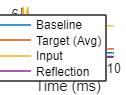

time_ms = time_s.*1000;
hold on
plot(time_ms, baselineAveraged_V + 5);
plot(time_ms, targetAveraged_V + 5.1);
plot(time_ms, input_V + 5.7);
plot(time_ms, reflection_V + 4.9);
legend("Baseline", "Target (Avg)", "Input", "Reflection")
xlabel("Time (ms)");

## 1 Degree of Freedom SONAR

With the SNR improved, key features in the signals can more easily be determined such as the time an acoustic pressure wave passes the microphone. Figure 3 shows a schematic of the path the acoustic pressure wave will travel from the source of sound for a 1-dimensional SONAR experiment which only calculates distance. The acoustic pressure wave generated by the speaker passes by the microphone at distance, $d_{\textrm{mic}-\textrm{source}}$, on the way to the target. After the acoustic wave passes the microphone it will travel a distance to the target object, $d_{\textrm{target}-\textrm{mic}}$. The wave then reflects off the target object and will pass by the microphone a second time at a much lower sound pressure level, traveling the same distance, $d_{\textrm{target}-\textrm{mic}}$. Using the time delays from the initial signal to when the wave first passes the microphone, the time delay of the reflection from when it passes the microphone and returns, and the speed of sound, the distance to the target from the sound source, $d_{\textrm{target}-\textrm{source}}$, can be calculated.  

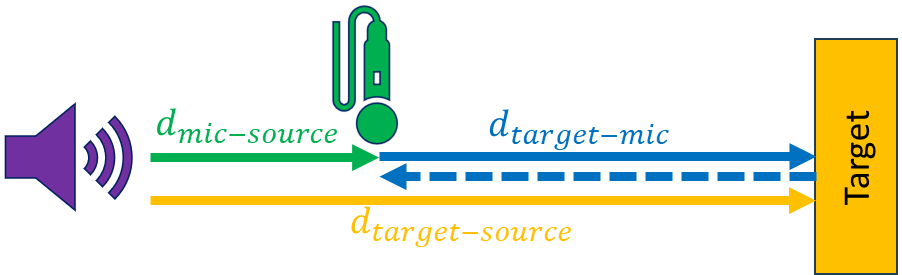

*Figure 3: Schematic of a one degree of freedom SONAR setup. *

### Speed of Sound

SONAR calculates the distance of an object by the time delay from an initial pressure pulse to the return reflection off an object and the local speed of sound of a medium. During the lab you will calculate the speed of sound of the ambient air based on its theoretical ideal gas relationship with temperature. For air you can assume the following properties:

gamma = 1.4; % Adiabatic index
R = 286.9; % J/kg*K, gas constant

#### Problem 5

If you measure the temperature to be 20.1 °C, what is the theoretical speed of sound in air, $c_{\textrm{theory}}$, in **m/s**? 

*(Hint: The speed of sound should be between 340 and 350 m/s). *

T_ambient = 20.1; % °C, ambient air temperature
% Formula: sqrt(gamma*R*(T_ambient + 273.15K))  
c_theory = sqrt(gamma.*R.*(T_ambient + 273.15)); % m/s

fprintf( 'c_theory = %.3f m/s\n', c_theory ); % Print answer

c_theory = 343.201 m/s


### Source to Microphone Distance

The time delay from when the acoustic pressure wave is generated at the speaker and to when it passes the microphone, ${\Delta t}_{\textrm{mic}}$, needs to be determined to calculate the microphone distance from the source, $d_{\textrm{mic}-\textrm{source}}$. By identifying similar features in the input and average baseline and their respective times, $t_{\textrm{input}}$ & $t_{\textrm{mic}}$, the time delay from when the wave is generated till it passes the microphone, ${\Delta t}_{\textrm{mic}}$, can be calculated. Any relevant feature in the signal can be used. However, it best to use prominent and readily identifiable features like a maximum or minimum. Once the time delay has been determined, the distance between the sound source and the microphone, $d_{\textrm{mic}-\textrm{source}}$, can be calculated using the speed of sound, $c_{\textrm{theory}}$.

#### Problem 6

What is the time of the first maximum peak of the input wave, $t_{\textrm{input}}$, in **milliseconds**? 

*(HINT:* *A simple method for retrieving the time values is to use the data cursor to find the time at the first peak of the signal from you figure in Problem 4. You can also find the time at the maximum of from the data using MATLAB functions like *max()* and *find() *with appropriate logic and constraints to make sure you are finding the maximum of the pressure wave voltage and not noise.)* 

*(Hint: it should be between 0.0 and 0.2 ms.)*

t_input = 0.125; % ms

fprintf( 't_input = %.3f ms\n', t_input ); % Print answer

t_input = 0.125 ms


#### Problem 7

What is the time of the first maximum peak of the average baseline wave when it reaches the microphone, $t_{\textrm{mic}}$, in **milliseconds**? 

*(Hint: it should be between 1.2 and 1.4 ms.)*

t_mic = 1.25; % ms

fprintf( 't_mic = %.3f ms\n', t_mic ); % Print answer

t_mic = 1.250 ms


#### Problem 8

What is the time delay between the source of sound and when the wave reaches the microphone, ${\Delta t}_{\textrm{mic}}$, in **milliseconds**? 

*(Hint: it should be between 1.0 and 1.2 ms.)*

delta_t_mic = t_mic - t_input; % ms

fprintf( 'Δt_mic = %.3f ms\n', delta_t_mic ); % Print answer

Δt_mic = 1.125 ms


#### Problem 9

What is the distance to the microphone from the source, $d_{\textrm{mic}-\textrm{source}}$, in **meters**? 

*(Hint: it should be between 0.3 and 0.4 m.)*

d_mic_source = (delta_t_mic.*c_theory).*1e-3; % m

fprintf( 'd_mic_source = %.3f m\n', d_mic_source ); % Print answer

d_mic_source = 0.386 m


### Microphone to Target Distance

The time delay from when the acoustic pressure wave first passes the microphone to when its reflection passes the microphone, ${\Delta t}_{\textrm{target}}$, can be used to determine the distance to the target object from the microphone.

#### Problem 10

What is the time of the first maximum peak of the relection wave, $t_{\textrm{reflection}}$, in **milliseconds**? 

*(Hint: it should be between 3.8 and 4.0 ms.)*

t_reflection = 3.9; % ms

fprintf( 't_input = %.3f ms\n', t_reflection ); % Print answer

t_input = 3.900 ms


#### Problem 11

What is the time delay between first passing of the pressure wave and the reflection wave of the microphone, ${\Delta t}_{\textrm{target}}$, in **milliseconds**? 

*(Hint: it should be between 2.5 and 2.7 ms.)*

delta_t_target = t_reflection - t_mic; % ms

fprintf( 'Δt_object = %.3f ms\n', delta_t_target ); % Print answer

Δt_object = 2.650 ms


#### Problem 12

What is the distance to the target object from the microphone, $d_{\textrm{target}-\textrm{mic}}$, in **meters**?

*(Hint: The total distance the wave travels is not the same as the distance to the target from the microphone!)*

*(Hint: It should be between 0.4 and 0.5 m.)*

d_target_mic = c_theory.*(delta_t_target./2).*1e-3;

fprintf( 'd_target = %.3f m\n', d_target_mic ); % Print answer

d_target = 0.455 m


### Source to Target Object Distance

The distance from the source of sound to the target object, $d_{\textrm{target}-\textrm{source}}$, can now be calculated from the two known distances, $d_{\textrm{mic}-\textrm{source}}$ & $d_{\textrm{target}-\textrm{mic}}$.

#### Problem 13

What is the distance to the target object from source of sound, $d_{\textrm{target}-\textrm{source}}$, in **meters**?

*(Hint: It should be between 0.8 and 0.9 m.)*

d_target_source = d_target_mic + d_mic_source; % m

fprintf( 'd_target_source = %.3f m\n', d_target_source ); % Print answer

d_target_source = 0.841 m


## Bias Error Correction

Frequently there can be a bias, offset, or delay in our experiments which can cause an error in our measurements. This can usually be correct by comparing the results to a known value or relationship and shifting the results. For this experiment, your client wants to use the front of the speaker as a reference point of the measurements, not the source of the sound which was used for our SONAR distance calculations. You will use the distance to the microphone from the speaker as a reference measurement to correct your distance calculations. This reference will be measured using a encoder on the microphone boom as shown in Figure 4.

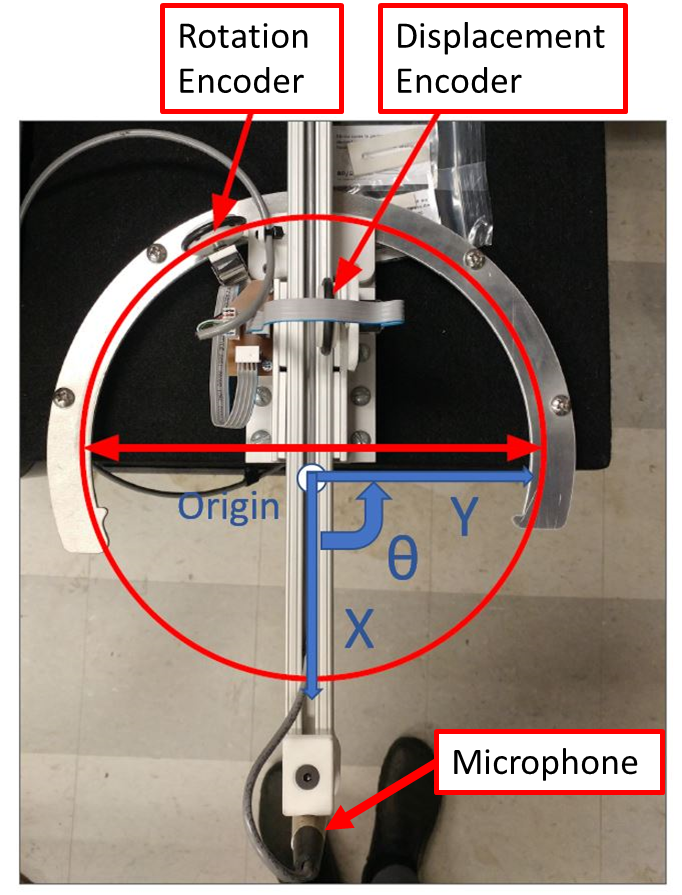

*Figure 4: Microphone boom assembly with position encoders and reference coordinate system. The displacement encoder can be used to measure the distance of the microphone from the speaker as a reference value.*

### Digital Encoder

The digital encoders used to determine the distance of the microphone from the speaker consists on an encoder attached to a wheel. When the boom of the microphone is flush with the speaker, the tick count will be set to 0. Counting the change in ticks from this reference point will allow you to calculate the rotation of the encoder and therefore the distance the boom has displaced using the wheel diameter.

The digital encoder you will use in lab have the following specifications:

s_encoder = 120; % ticks/rev, encoder sensitivity
D_wheel = 0.0411; % m, encoder wheel diameter

#### Problem 14

If the encoder has measured a change of 277.75 ticks, what is the distance of microphone from the reference point, $d_{\textrm{mic}}$, in **meters**?

*(Hint: It should be between 0.25 and 0.35 m.)*

tick_count = 277.75;

% formula = (tick_count*pi*wheelDiameter)/(encoderSensitivity)
d_mic = tick_count*pi*D_wheel/s_encoder; % m, boom displacements

fprintf( 'd_mic = %.3f m\n', d_mic ); % Print answer

d_mic = 0.299 m


### Bias Error

With an accurate location of the microphone relative to the reference known, the calculated distance from the signal can be corrected for the offset or bias error. First you will have to calculate the distance to apparent the source of sound from the reference location, $d_{\textrm{source}}$. You can then use this to correct the calculations of the distance relative to the sound source.

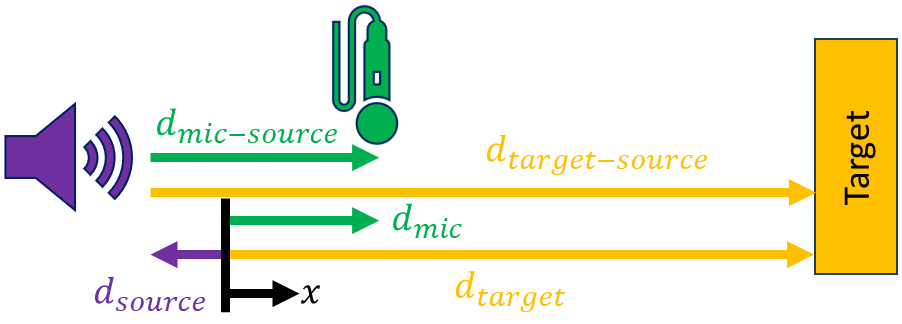

Figure 4: *Schematic of a one degree of freedom SONAR setup with reference location offset from the source of sound. *

#### Problem 15

Using the calculated distance of microphone from both the encoder, $d_{\textrm{mic}}$, and the signal, $d_{\textrm{mic}-\textrm{source}}$, what is the distance to the apparent source of sound from the reference point, $d_{\textrm{source}}$, in **meters**?

*(Hint: It should be between -0.1 and 0.0 m.)*

% Code here to solve for d_source
d_source = d_mic - d_mic_source; % m

fprintf( 'd_source = %.3f m\n', d_source ); % Print answer

d_source = -0.087 m


#### Problem 16

What is the distance to the target object from the reference point, $d_{\textrm{target}}$, in **meters**?

*(Hint: It should be between 0.7 and 0.8 m.)*

% Code here to solve for d_target
d_target = d_target_source + d_source; % m 

fprintf( 'd_target = %.3f m\n', d_target ); % Print answer

d_target = 0.754 m
